## **1.**

**Crie os seguintes sinais num ficheiro do MATLAB, usando um período de amostragem 𝑇𝑎 = 0.01 segundos.**

**a) 𝑥(𝑡) = 2 sin(4𝜋𝑡) , 𝑡 ∈ [0; 5]**

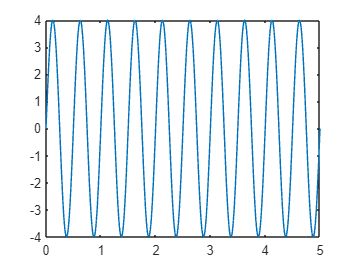

t = 0:0.01:5;
x_t = 2*sin(4*pi*t);
plot(t, 2 * x_t)

**b) 𝑦(𝑡) = cos(10𝜋𝑡) , 𝑡 ∈ [0; 5]**

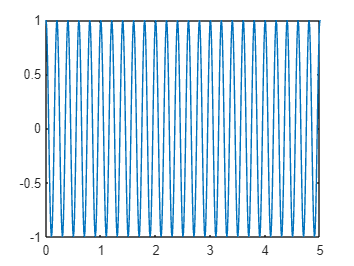

y_t = cos(10*pi*t);
plot(t, y_t)

**c) 𝑧(𝑡) = 𝑥(𝑡)𝑦(𝑡)**

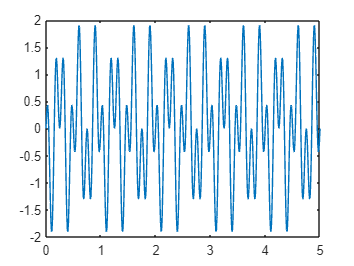

z_t =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 … ] (1×501 double)
              YData: [0 0.2384 0.4024 0.4328 0.2977 7.1983e-17 -0.4231 -0.9058 -1.3662 -1.7211 -1.9021 -1.8684 -1.6148 -1.1733 -0.6071 -3.4941e-16 0.5592 0.9926 1.2467 1.3021 1.1756 0.9163 0.5956 0.2924 0.0775 7.4988e-32 0.0775 0.2924 … ] (1×501 double)

  Show 

z_t = plot(t, x_t .* y_t)

**d) 𝑤(𝑡) = 3 sin(𝜋𝑡) + 2 sin(6𝜋𝑡) , 𝑡 ∈ [0; 10]**

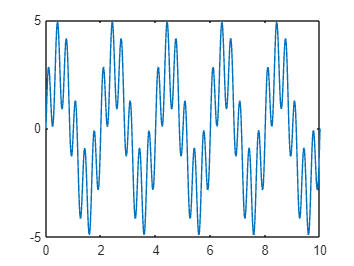

t = 0:0.01:10;
w_t = 3*sin(pi*t) + 2*sin(6*pi*t);
plot(t, w_t)

**e) 𝑞(𝑡1, 𝑡2) = 2 sin(2𝜋(2𝑡1 + 𝑡2)), 𝑡1, 𝑡2 ∈ [0; 5]**

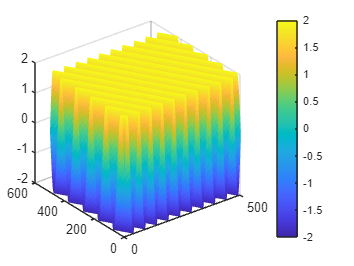

t1 = 0:0.01:5;
t2 = 0:0.01:5;
[XX, YY] = meshgrid(t1,t2);
%%plot(XX,YY(:,1),"k")
%%plot(XX(1,:),YY',"k")
q_t1t2 = 2*sin(2*pi*(2*XX+YY));
surf(q_t1t2, "EdgeColor", "none")
colorbar
hold off

## **2.**

**Represente cada um dos sinais da alínea 1 através de um gráfico individual. Averigue o espaço de memória que cada sinal ocupa, e comente se o período de amostragem considerado se adequa a cada sinal. Veja as diferenças que obteria se considerasse 𝑇𝑎 = 0.1  segundos**

## **3.**

**Represente simultaneamente os quatro primeiros sinais da alínea 1 num único gráfico, atribuindo as seguintes características gráficas a cada sinal:**

**𝑥(𝑡) – traço contínuo e fino, de cor vermelha**

**y(𝑡) – traço grosso a tracejado, de cor azul**

**z(𝑡) – traço contínuo e fino, de cor verde, com pontos em cada amostra**

**𝑤(𝑡) – traço contínuo e grosso, de cor amarela**

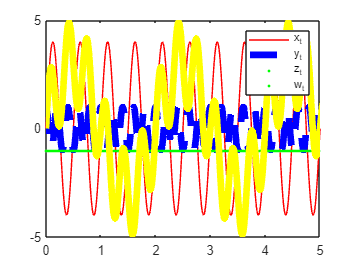

t = 0:0.01:5;
plot(t, 2 * x_t, "r","LineWidth", 0.01)
hold on
plot(t, y_t, "b--", "LineWidth", 5)
t = 0:0.01:10;
plot(t, z_t, "g.", "LineWidth", 0.01)
plot(t, w_t, "y", "LineWidth", 5)
hold off

axis([0 5 -5 5])
legend("x_t","y_t","z_t","w_t")

**4. Considere agora o seguinte sinal dependente de duas variáveis, 𝑥1 e 𝑥2, sendo também dependente do tempo, 𝑡: **

**r(x1,x2,t) = 2sin(2*pi * sqrt(x1^2 + x2^2) - 2*pi*t)**

**x1, x2 € [-5, 5]**

**Considerando o período de amostragem 𝑇𝑎 = 1/25 segundos para a variável 𝑡 ∈ [0; 5] segundos, elabore um pequeno script que apresente as sucessivas “imagens” 2D que 𝑟(𝑥1, 𝑥2, 𝑡(𝑘)), 𝑘 = 1, … , 𝑁, apresenta à medida que o tempo 𝑡 vai progredindo.**

passo = 1/25;
t = 0:passo:5;
Nmax = length(t);
k = 1:126;
x1 = linspace(-5,5,126);
x2 = linspace(-5,5,126);

r = 2 * sin(2*pi*sqrt(x1.^2 + x2.^2) - 2*pi*t);

plot(t, r)